[https://kr.mathworks.com/help/lidar/ug/build-map-from-2d-lidar-scans-using-slam.html?searchHighlight=2d%20lidar&s_tid=srchtitle_2d%20lidar_2](https://kr.mathworks.com/help/lidar/ug/build-map-from-2d-lidar-scans-using-slam.html?searchHighlight=2d%20lidar&s_tid=srchtitle_2d%20lidar_2)

load('data8.mat');


scans{1}

ans =   lidarScan - 속성 있음:

       Ranges: [584×1 double]
       Angles: [584×1 double]
    Cartesian: [584×2 double]
        Count: 584


Full data SLAM

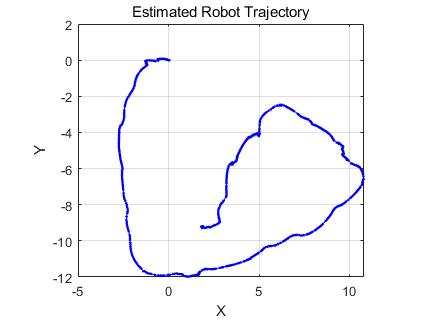

% Set maximum lidar range to be slightly smaller than maximum range of the
% scanner, as the laser readings are less accurate near maximum range
maxLidarRange = 8;
% Set the map resolution to 10 cells per meter, which gives a precision of 10cm
mapResolution = 10;
% Create a pose graph object and define information matrix
pGraph = poseGraph;
infoMat = [1 0 0 1 0 1];
% Loop over each scan and estimate relative pose
prevScan = scans{1};
for i = 2:numel(scans)
    currScan = scans{i};
    % Estimate relative pose between current scan and previous scan
    [relPose,stats] = matchScansGrid(currScan,prevScan, ...
        'MaxRange',maxLidarRange,'Resolution',mapResolution);
    % Refine the relative pose
    relPoseRefined = matchScans(currScan,prevScan,'initialPose',relPose);
    % Add relative pose to the pose graph object
    pGraph.addRelativePose(relPoseRefined,infoMat);
    ax = show(pGraph,'IDs','off');
    title(ax,'Estimated Robot Trajectory')
    drawnow
    prevScan = currScan;
end

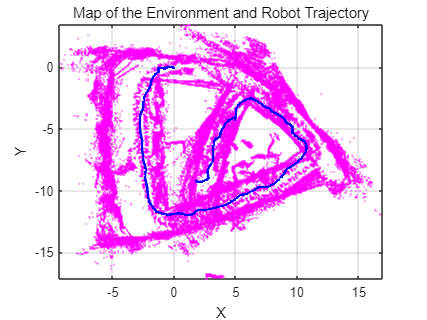


hFigMap = figure;
axMap = axes('Parent',hFigMap);
helperShow(scans,pGraph,maxLidarRange,axMap);
title(axMap,'Map of the Environment and Robot Trajectory')

1/5 data SLAM

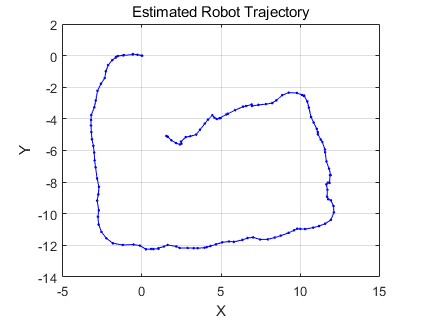

% Set maximum lidar range to be slightly smaller than maximum range of the
% scanner, as the laser readings are less accurate near maximum range
maxLidarRange = 8;
% Set the map resolution to 10 cells per meter, which gives a precision of 10cm
mapResolution = 10;
% Create a pose graph object and define information matrix
pGraph = poseGraph;
infoMat = [1 0 0 1 0 1];
% Loop over each scan and estimate relative pose
prevScan = scans{1};
for i = 2:5:numel(scans)
    currScan = scans{i};
    % Estimate relative pose between current scan and previous scan
    [relPose,stats] = matchScansGrid(currScan,prevScan, ...
        'MaxRange',maxLidarRange,'Resolution',mapResolution);
    % Refine the relative pose
    relPoseRefined = matchScans(currScan,prevScan,'initialPose',relPose);
    % Add relative pose to the pose graph object
    pGraph.addRelativePose(relPoseRefined,infoMat);
    ax = show(pGraph,'IDs','off');
    title(ax,'Estimated Robot Trajectory')
    drawnow
    prevScan = currScan;
end

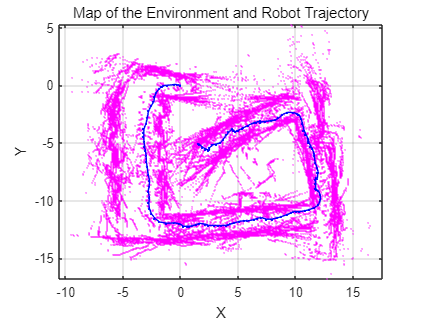


hFigMap = figure;
axMap = axes('Parent',hFigMap);
helperShow(scans(1:5:end),pGraph,maxLidarRange,axMap);
title(axMap,'Map of the Environment and Robot Trajectory')

1/8 data SLAM

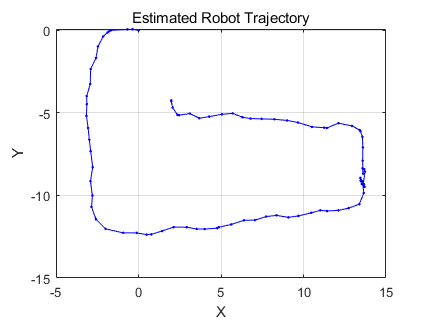

% Set maximum lidar range to be slightly smaller than maximum range of the
% scanner, as the laser readings are less accurate near maximum range
maxLidarRange = 8;
% Set the map resolution to 10 cells per meter, which gives a precision of 10cm
mapResolution = 10;
% Create a pose graph object and define information matrix
pGraph = poseGraph;
infoMat = [1 0 0 1 0 1];
% Loop over each scan and estimate relative pose
prevScan = scans{1};
for i = 2:8:numel(scans)
    currScan = scans{i};
    % Estimate relative pose between current scan and previous scan
    [relPose,stats] = matchScansGrid(currScan,prevScan, ...
        'MaxRange',maxLidarRange,'Resolution',mapResolution);
    % Refine the relative pose
    relPoseRefined = matchScans(currScan,prevScan,'initialPose',relPose);
    % Add relative pose to the pose graph object
    pGraph.addRelativePose(relPoseRefined,infoMat);
    ax = show(pGraph,'IDs','off');
    title(ax,'Estimated Robot Trajectory')
    drawnow
    prevScan = currScan;
end

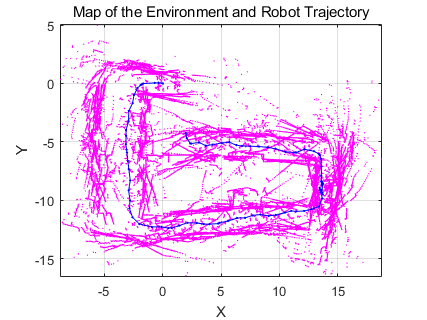


hFigMap = figure;
axMap = axes('Parent',hFigMap);
helperShow(scans(1:8:end),pGraph,maxLidarRange,axMap);
title(axMap,'Map of the Environment and Robot Trajectory')